# **Convolutional Neural Network: MSTAR **

## **Load and Explore Image Data**

Load the digit sample data as an image datastore. `imageDatastore` automatically labels the images based on folder names and stores the data as an `ImageDatastore` object. An image datastore enables you to store large image data,  including data that does not fit in memory, and efficiently read batches of images during training of a convolutional neural network.

file_path = 'PreprocessedData2';
digitDatasetPath = fullfile(file_path);
imds = imageDatastore(digitDatasetPath,'IncludeSubfolders',true,'LabelSource','foldernames');

Display some of the images in the datastore.

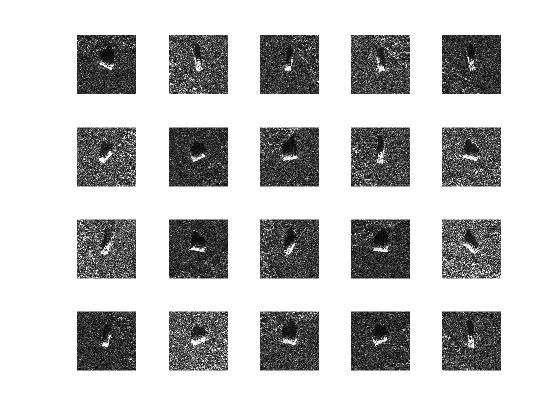

num_images = 195;
figure;
perm = randperm(num_images,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

Calculate the number of images in each category. `labelCount` is a table that contains the labels and the number of images having  each label. You can specify the number of classes  in the last fully connected layer of your network as the `OutputSize` argument.

labelCount = countEachLabel(imds)

labelCount = 8×2 table
     Label      Count
    ________    _____

    2S1          577 
    BRDM-2       697 
    BTR-60       195 
    D7           274 
    SLICY       1953 
    T62          273 
    ZIL131       274 
    ZSU-23_4     696 


## **Specify Training and Validation Sets**

Divide the data into training and validation data sets, so that each  category in the training set contains  images, and the validation set contains the remaining images from each label. `splitEachLabel` splits the datastore `digitData` into two new datastores, `trainDigitData` and `valDigitData`.

numTrainFiles = 170;
numVFiles = 25;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles, numVFiles,'randomize');

## **Define Network Architecture**

Define the convolutional neural network architecture.

layers = [
    imageInputLayer([200 200 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(8)
    softmaxLayer
    classificationLayer]

layers =   15x1 Layer array with layers:

     1   ''   Image Input             200x200x1 images with 'zerocenter' normalization
     2   ''   Convolution             8 3x3 convolutions with stride [1  1] and padding 'same'
     3   ''   Batch Normalization     Batch normalization
     4   ''   ReLU                    ReLU
     5   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     6   ''   Convolution             16 3x3 convolutions with stride [1  1] and padding 'same'
     7   ''   Batch Normalization     Batch normalization
     8   ''   ReLU                    ReLU
     9   ''   Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
    10   ''   Convolution             32 3x3 convolutions with stride [1  1] and padding 'same'
    11   ''   Batch Normalization     Batch normalization
    12   ''   ReLU                    ReLU
    13  

**Image Input Layer** An `imageInputLayer` is where you specify the image size. These numbers correspond to the height, width, and the  channel size. If the data consists of grayscale images, the  channel size (color channel) is 1. For a color image, the channel size  is 3, corresponding to the RGB values. You do not need to shuffle the  data because `trainNetwork`, by default, shuffles the data at the beginning of training. `trainNetwork` can also automatically shuffle the data at the beginning of every epoch during training.

**Convolutional Layer** In the convolutional layer, the first argument is `filterSize`, which is the height and width of the filters the training function uses while scanning along the images. In this example, the number 3  indicates that the filter size is 3-by-3. You can specify different  sizes for the height and width of the filter. The second argument is the number of filters, `numFilters`, which is  the number of neurons that connect to the same region of the input. This parameter determines the number of feature maps. Use the `'Padding'` name-value pair to add padding to the input feature map. For a convolutional layer with a default stride of 1, `'same'` padding ensures that the spatial output size is the same as the input  size. You can also define the stride and learning rates for this layer  using name-value pair arguments of `convolution2dLayer`.

**Batch Normalization Layer** Batch normalization layers normalize the activations and gradients  propagating through a network, making network training an easier  optimization problem. Use batch normalization layers between  convolutional layers and nonlinearities, such as ReLU layers, to speed  up network training and reduce the sensitivity to network  initialization. Use `batchNormalizationLayer` to create a batch normalization layer.

**ReLU Layer** The batch normalization layer is followed by a nonlinear activation  function. The most common activation function is the rectified linear  unit (ReLU). Use `reluLayer` to create a ReLU layer.

**Max Pooling Layer** Convolutional layers (with activation functions) are sometimes followed by a down-sampling operation that reduces the spatial size of the  feature map and removes redundant spatial information. Down-sampling  makes it possible to increase the number of filters in deeper  convolutional layers without increasing the required amount of  computation per layer. One way of down-sampling is using a max pooling,  which you create using  `maxPooling2dLayer`. The max pooling layer returns the maximum values of rectangular regions of inputs, specified by the first argument, `poolSize`. In this example, the size of the rectangular region is [2,2]. The `'Stride'` name-value pair argument specifies the step size that the training function takes as it scans along the input.

**Fully Connected Layer** The convolutional and down-sampling layers are followed by one or more  fully connected layers. As its name suggests, a fully connected layer is a layer in which the neurons connect to all the neurons in the  preceding layer. This layer combines all the features learned by the  previous layers across the image to identify the larger patterns. The  last fully connected layer combines the features to classify the images. Therefore, the `OutputSize` parameter in the last fully connected layer is equal to the number of classes in the  target data. In this example, the output size is 10, corresponding to  the 10 classes. Use `fullyConnectedLayer` to create a fully connected layer.

**Softmax Layer** The softmax activation function normalizes the output of the fully  connected layer. The output of the softmax layer consists of positive  numbers that sum to one, which can then be used as classification  probabilities by the classification layer. Create a softmax layer using  the `softmaxLayer` function after the last fully connected layer.

**Classification Layer** The final layer is the classification layer. This layer uses the  probabilities returned by the softmax activation function for each input to assign the input to one of the mutually exclusive classes and  compute the loss. To create a classification layer, use `classificationLayer`.

## **Specify Training Options**

After defining the network structure, specify the training options.  Train the network using stochastic gradient descent with momentum (SGDM) (with an initial learning rate of 0.01. Set the maximum number of epochs to 4). An epoch is a full training cycle on the entire training data  set. Monitor the network accuracy during training by specifying  validation data and validation frequency. Shuffle the data every epoch.  The software trains the network on the training data and calculates the  accuracy on the validation data at regular intervals during training.  The validation data is not used to update the network weights. Turn on  the training progress plot, and turn off the command window output.

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

## **Train Network Using Training Data**

Train the network using the architecture defined by `layers`, the training data, and the training options. By default, `trainNetwork` uses a GPU if one is available (requires Parallel Computing Toolbox™  and a CUDA® enabled GPU with compute capability 3.0 or higher).  Otherwise, it uses a CPU. You can also specify the execution environment by using the `'ExecutionEnvironment'` name-value pair argument of `trainingOptions`.

The training progress plot shows the mini-batch loss and accuracy and the  validation loss and accuracy. For more information on the training  progress plot, see Monitor Deep Learning Training Progress. The loss is the cross-entropy loss. The accuracy is the percentage of images that the network classifies correctly.

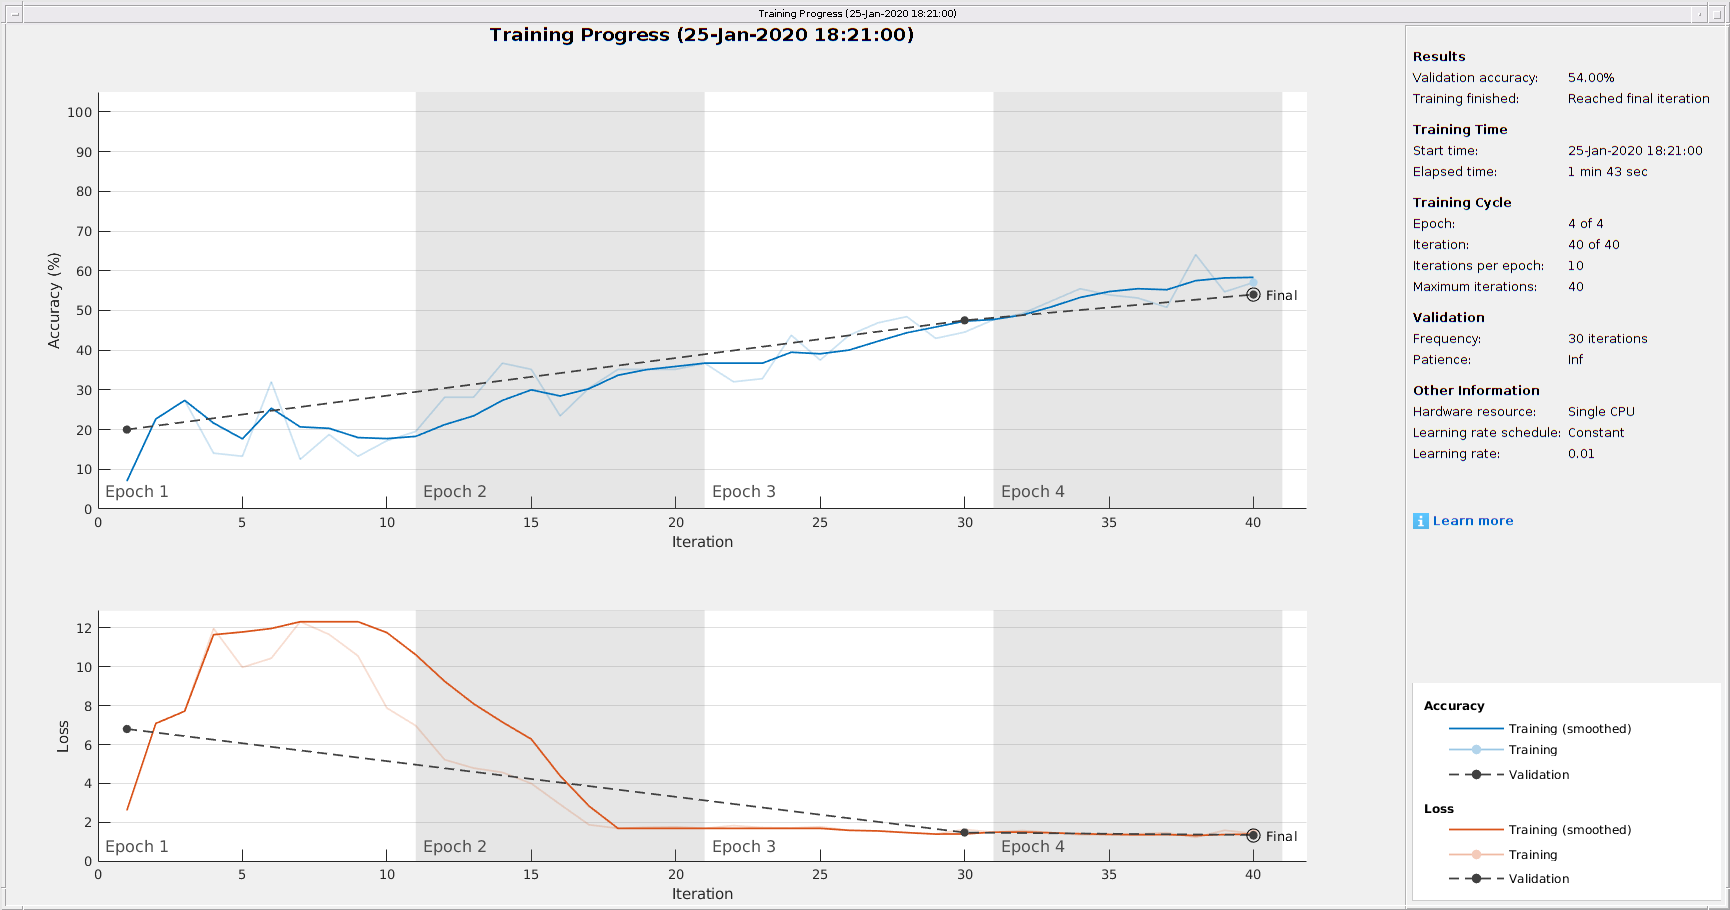

net = trainNetwork(imdsTrain,layers,options);

## **Classify Validation Images and Compute Accuracy**

Predict the labels of the validation data using the trained network, and calculate the final validation accuracy. Accuracy is the fraction of  labels that the network predicts correctly.

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels

YValidation = 200×1 categorical array
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     2S1 
     BRDM-2 
     BRDM-2 
     BRDM-2 
     BRDM-2 
     BRDM-2 



accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.5400

## Performance calculation measures

- Accuracy

- F1 Score, Recall, Precision

- Sensitivity and Specificity

**Precision** attempts to answer the following question: What proportion of positive identifications was actually correct?

Precision = $\frac{\textrm{TP}}{\textrm{TP}+\textrm{FP}}$

**Recall** attempts to answer the following question: What proportion of actual positives was identified correctly?

Recall = $\frac{\textrm{TP}}{\textrm{TP}+\textrm{FN}}$

labels_n = ["2S1", "BRDM-2", "BTR-60", "D7", "SLICY", "T62", "ZIL131", "ZSU-23_4"];
x = size(YPred);
n = x(:,1);
C_values = zeros(2, n, 8);
for i = 1:8
    C_values(1,:, i) = (YPred == labels_n(:,i))';
    C_values(2,:, i) = (YValidation == labels_n(:,i))';
end

preformance_mesures = zeros(8, 3);

for i = 1:8
    TP = sum(((C_values(1,:,i) == 1) & (C_values(2,:,i) == 1)));
    FP = sum(((C_values(1,:,i) == 1) & (C_values(2,:,i) == 0)));
    TN = sum(((C_values(1,:,i) == 0) & (C_values(2,:,i) == 0)));
    FN = sum(((C_values(1,:,i) == 0) & (C_values(2,:,i) == 1)));
    precision = (TP)/(TP + FP);
    recall = (TP)/(TP + FN);
    f1_score = (2*precision*recall)/(recall + precision);
    preformance_mesures(i, 1) = precision;
    preformance_mesures(i, 2) = recall;
    preformance_mesures(i, 3) = f1_score;
end

preformance_mesures

preformance_mesures =     0.8750    0.2800    0.4242
    0.4348    0.4000    0.4167
    0.6667    0.7200    0.6923
    0.8889    0.6400    0.7442
    0.6000    0.7200    0.6545
    0.3953    0.6800    0.5000
    0.4783    0.4400    0.4583
    0.3929    0.4400    0.4151
